clear; close; clc;

## Initialization and Decaleration

D_duct = convlength(1.5, "in", "m") % duct diameter (m)

D_duct = 0.0381

D_body = convlength(3.5, "in", "m") % body diameter at max duct thickness (m)

D_body = 0.0889

D_nose = convlength(3.5, "in", "m") % body diameter at fairing body join (m)

D_nose = 0.0889

L = .1 % length of cone (m)

L = 0.1000


% number of points to use intriangualrization of frustum
n_frustum_points = 100;

% convert geometries
% diameter to radius

r_0 = D_duct/2 % duct raidus (m)

r_0 = 0.0190

r_1 = D_body/2 % body raidus (m)

r_1 = 0.0444

r_2 = D_nose/2 % nose raidus (m)

r_2 = 0.0444


% solve for exterior tangent intersection points

x_6 = 2*r_0*r_1 / (r_0 + r_1) * sqrt(r_1/r_0); % x coordinate of intersection of tangent with body (m) 
x_8 = 2*r_0*r_1 / (r_0 + r_1) * sqrt(r_0/r_1); % x coordinate of intersection of tangent with duct (m) 
y_6 = r_1 * (r_1 - r_0) / (r_0 + r_1); % y coordinate of intersection of tangent with body (m) 
y_8 = r_1 + r_0 + r_0 * (r_1 - r_0) / (r_0 + r_1); % y coordinate of intersection of tangent with duct (m) 

% body

% create mesh of x cordinates
x=linspace(-r_0,r_0);
x=linspace(-r_1,r_1);

% plot the body
plot(x,sqrt(r_1^2 - x.^2), "-k")
axis equal
hold on
plot(x,-sqrt(r_1^2 - x.^2), "-k")

% duct

% create mesh of x cordinates
x=linspace(-r_1,r_1);
x=linspace(-r_0,r_0);

% plot the duct
plot(x,sqrt(r_0^2 - x.^2) + (r_0+r_1), "-k")
axis equal
hold on
plot(x,-sqrt(r_0^2 - x.^2) + (r_0+r_1), "-k")

% plot the points of tangency
% xline(x_6, "--r", "x_6")
% xline(x_8, "--r", "x_8")
% yline(y_6, "--r", "y_6")
% yline(y_8, "--r", "y_8")

plot(x_6,y_6,"-rs")
plot(x_8,y_8,"-rs")

% tangent

% create mesh of x cordinates
x=linspace(x_8,x_6);

% plot the tangent line
plot(x,y_6 + (y_8-y_6)/(x_8-x_6)* (x-x_6), "-", "Color","#A2142F")

% to show that I can plot the perimiter of the sheet I need to plot the
% exterior sections of the duct and body
% duct
x=linspace(0,x_8);
plot(x,sqrt(r_0^2 - x.^2) + (r_0+r_1), "-b")
plot(0, 2*r_0 + r_1, "-sb")
% body
x=linspace(x_6,r_1)

x =     0.0407    0.0408    0.0408    0.0409    0.0409    0.0409    0.0410    0.0410    0.0410    0.0411    0.0411    0.0412    0.0412    0.0412    0.0413    0.0413    0.0413    0.0414    0.0414    0.0415    0.0415    0.0415    0.0416    0.0416    0.0416    0.0417    0.0417    0.0418    0.0418    0.0418    0.0419    0.0419    0.0419    0.0420    0.0420    0.0421    0.0421    0.0421    0.0422    0.0422    0.0422    0.0423    0.0423    0.0424    0.0424    0.0424    0.0425    0.0425    0.0425    0.0426



plot(x,sqrt(r_1^2 - x.^2), "-m")
plot(r_1, 0, "-sm")

% plot the surface to mesh to
x=linspace(x_6,r_1);

% here are soome quick caluclations of the conical frustum that i will need
psi = pi/2 - atan2(y_6, x_6) % angle of transfer from circle to tangent (radians)

psi = 1.1593

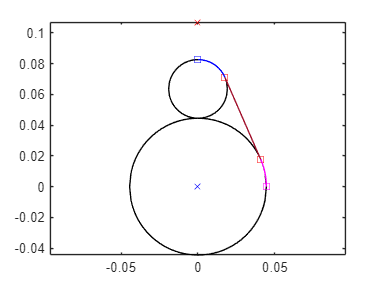


% development of the frustum
development_points = develop_oblique_conical_frustum([0, r_0+r_1], r_0, [0,0], r_1, L, 0, psi, n_frustum_points);

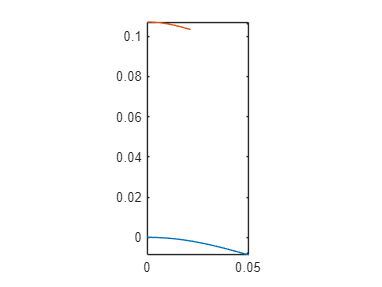


figure
plot(development_points(:,1,1), development_points(:,1,2))
hold on
plot(development_points(:,2,1), development_points(:,2,2))
% step 0 draw verticle line from 1 to A
axis equal
ylim([min(development_points(:,:,2),[],"all"), max(development_points(:,:,2),[],"all")])
xlim([min(development_points(:,:,1),[],"all"), max(development_points(:,:,1),[],"all")])

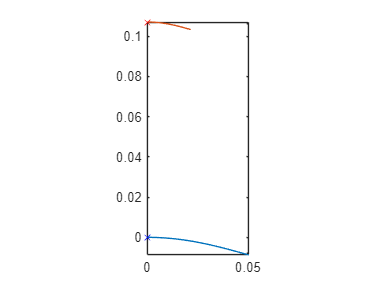

% print settinggs
% units: cm
% height: 19.04 cm
% width: 14.27 cm

figure
plot(development_points(:,1,1), development_points(:,1,2))
hold on
plot(development_points(:,2,1), development_points(:,2,2))
% step 0 draw verticle line from 1 to A
axis equal
ylim([min(development_points(:,:,2),[],"all"), max(development_points(:,:,2),[],"all")])
xlim([min(development_points(:,:,1),[],"all"), max(development_points(:,:,1),[],"all")])

% create the second cylinder
% development_points = develop_oblique_conical_frustum([0, r_0+r_1], r_1, [0,0], r_1, L, psi, pi/2, n_frustum_points);
% development_points = development_points + development_points(end,1,:); % offset to ensure contact with approriate point
% development_points(:,:,1) = development_points(:,:,1) + development_points(end,1,1);
% development_points(:,:,2) = development_points(:,:,2) + development_points(end,1,2);
% 
% plot(development_points(:,1,1), development_points(:,1,2),"--c")
% plot(development_points(:,2,1), development_points(:,2,2),"--m")

% triangulate arc 1B
% step 1 intersection of triangulated arc 1B with arc AB

% step 2 triangulate arc B2
% intersection of triangulated arc B2 with arc 12

H=L;
phi = 0;
theta = linspace(phi,psi, n_frustum_points)'; % angles of frustum
o_0 = [0, r_0+r_1];
o_1 = [0,0];

% produce the points on the circle
small_circ_coords = [r_0*sin(theta) + o_0(1), r_0*cos(theta) + o_0(2)]; % coordinate of points on the duct that are on the frustum
large_circ_coords = [r_2*sin(theta) + o_1(1), r_2*cos(theta) + o_1(2)]; % % coordinate of points on the body that are on the frustum

% produce tangent lines
x_tangent = linspace(x_8,x_6, n_frustum_points);
y_tangent = y_6 + (y_8-y_6)/(x_8-x_6)* (x_tangent-x_6);

% append the points
small_circ_coords = [small_circ_coords; [x_tangent',y_tangent']];
large_circ_coords = [large_circ_coords; repmat(large_circ_coords(end,:),n_frustum_points,1)];

% produce the final frustum
theta = linspace(psi,pi/2, n_frustum_points)';
final_frust_outer = [r_1*sin(theta) + o_1(1), r_1*cos(theta) + o_1(2)];
final_frust_inner = [r_2*sin(theta) + o_1(1), r_2*cos(theta) + o_1(2)];

% append the points
small_circ_coords = [small_circ_coords; final_frust_outer];
large_circ_coords = [large_circ_coords; final_frust_inner];


% to complete the circle
% mirror vertically
ssc_orig = small_circ_coords;
lsc_orig = large_circ_coords;
% currently commetend for new thing
% small_circ_coords = [small_circ_coords; flipud([ssc_orig(:,1), -ssc_orig(:,2)])];
% large_circ_coords = [large_circ_coords; flipud([lsc_orig(:,1), -lsc_orig(:,2)])];


% development points [(point number), (lower or upper surface), (x or y)]
development_points = zeros([n_frustum_points, 2, 2]); % points of the deveoped frustum

% triangulate point A_1

% cross section lengths
% distance between poinst on small and points on large circle
tri_dists_s_2_l = vecnorm([repelem(H,length(small_circ_coords)-1)', abs(small_circ_coords(1:end-1,:) - large_circ_coords(2:end,:))],2,2); % distance between poinst on small and points on large circle (diagonal)
tri_dists_l_2_s = vecnorm([repelem(H,length(small_circ_coords))', abs(small_circ_coords(1:end,:) - large_circ_coords(1:end,:))],2,2); % distance between poinst on large and points on small circle ("verticle")


% acr lengths on surface
small_circ_arc_len = vecnorm(diff(small_circ_coords),2,2); % distances between points of small circle
large_circ_arc_len = vecnorm(diff(large_circ_coords),2,2); % distances between points of large circle

% initialize points
development_points(1,1,:) = [0,0]; % add the initial point of the development (lower)
development_points(1,2,:) = [0,tri_dists_l_2_s(1)]; % add the initial point of the development (upper)

curr_lower = squeeze(development_points(1,1,:));
curr_upper = squeeze(development_points(1,2,:));

%debug plottinh
plot(curr_lower(1), curr_lower(2),"-xb")
plot(curr_upper(1), curr_upper(2),"-xr")

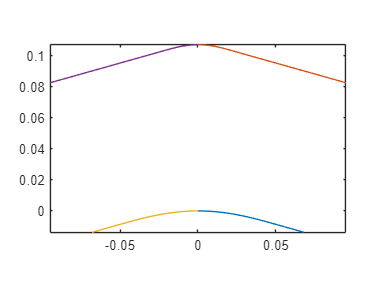


% Triangularization algorithm

for i = 1:length(small_circ_coords)-1
    %get the lower point
    % get posible intersection points
    [x_int, y_int] = circle_interception(curr_lower, large_circ_arc_len(i), curr_upper, tri_dists_s_2_l(i));
    [x_int, int_index] = max(x_int); % get the rightmost intercept and which index it corresponds to
    y_int = y_int(int_index);
    % store the point
    development_points(i+1,1,:) = [x_int, y_int];
    curr_lower = squeeze(development_points(i+1,1,:));

    % find the next upper point
    [x_int, y_int] = circle_interception(curr_lower, tri_dists_l_2_s(i+1), curr_upper, small_circ_arc_len(i));
    [x_int, int_index] = max(x_int); % get the rightmost intercept and which index it corresponds to
    y_int = y_int(int_index);
    % store the point
    development_points(i+1,2,:) = [x_int, y_int];
    curr_upper = squeeze(development_points(i+1,2,:));
end
development_points = real(development_points);
   
figure
plot(development_points(:,1,1), development_points(:,1,2))
hold on
plot(development_points(:,2,1), development_points(:,2,2))
% step 0 draw verticle line from 1 to A
axis equal
ylim([min(development_points(:,:,2),[],"all"), max(development_points(:,:,2),[],"all")])
xlim([min(development_points(:,:,1),[],"all"), max(development_points(:,:,1),[],"all")])
% if mirroring do the next bit
ylim([min(development_points(:,:,2),[],"all"), max(development_points(:,:,2),[],"all")])
xlim([-max(development_points(:,:,1),[],"all"), max(development_points(:,:,1),[],"all")])

plot(-development_points(:,1,1), development_points(:,1,2))
hold on
plot(-development_points(:,2,1), development_points(:,2,2))

% for 4 in tube:
% D_duct = convlength(1.65, "in", "m") % duct diameter (m)
% D_body = convlength(4, "in", "m") % body diameter at max duct thickness (m)
% D_nose = convlength(4, "in", "m") % body diameter at fairing body join (m)
% L = .1 % length of cone (m)
% print settinggs
% units: cm
% height: 27.56 cm
% width: 20.66 cm

% for 3.5 in tube:
% D_duct = convlength(1.5, "in", "m") % duct diameter (m)
% D_body = convlength(3.5, "in", "m") % body diameter at max duct thickness (m)
% D_nose = convlength(3.5, "in", "m") % body diameter at fairing body join (m)
% L = .1 % length of cone (m)
% print settinggs
% units: cm
% height: 24.57 cm
% width: 18.41 cm

% total length of the eccentric cross section
P = 4 * sum(vecnorm(diff([development_points(:,2,1), development_points(:,2,2)]),2,2)) % perimeter of full duct

P = 0.3943

% this is found by taking all the points of the upper surface of a quater
% of the duct. finding the difference in there coordinates then taking the
% norm of the differences to yeild the distance between the points. finaly
% the distances are sumed to get the perimeter and multiplied by 4 to get
% the fill ductm, /



T = sqrt((x_8-x_6).^2 + (y_8-y_6).^2) % length of tangent

T = 0.0582

d = sqrt((r_1-r_0).^2 + L.^2)

d = 0.1032

R_0 = d*r_0 / (r_1-r_0)

R_0 = 0.0774

R_1 = d + R_0

R_1 = 0.1806

C = (-(psi-pi/2)) * r_1 % length of faring the lies on th body (from centerline to tengent point) - x2 for full body contact lenght

C = 0.0183

phi = 2*pi*r_1/R_1

phi = 1.5468

rad2deg(phi )

ans = 88.6258



% coordinate for conical frustum